clc;clear;
i=1;j=2;
gmipath=dir('.\f35*');
lon=(0.125-180:1/4:359.875-180);lat=(-89.875:1/4:89.875);[lat,lon]=meshgrid(lat,lon);
lonlim=[-45 -30];latlim=[60 67];
gmipath

gmipath = 包含以下字段的 3×1 struct 数组:
    name
    folder
    date
    bytes
    isdir
    datenum


gmiread=[gmipath(i).folder '\' gmipath(i).name];
fprintf(['GMI file reading -> ' gmipath(i).name '\n']);

GMI file reading -> f35_20171115v8.2


[time,sst,wspdLF,wspdMF,vapor,cloud,rain]=read_gmi_day_v8(gmiread);

E:\scholar\polar_low\work\20211109 track2017-11-15\gmi\f35_20171115v8.2


vapor(vapor>=250)=nan;rain(rain>=250)=nan;cloud(cloud>=250)=nan;time(time>=250)=nan;
wspdMF(wspdMF>=250)=nan;sst(sst>=250)=nan;wspdMF(wspdMF>=250)=nan;
time=rmss_data_change(time);vapor=rmss_data_change(vapor);cloud=rmss_data_change(cloud);
rain=rmss_data_change(rain);sst=rmss_data_change(sst);wspdMF=rmss_data_change(wspdMF);
ctrtime=reshape(time(floor((mean(lonlim)+180)*4),floor((mean(latlim)+90)*4),:),1,2);
[a,b]=find(abs(lon-min(lonlim))==min(min(abs(lon-min(lonlim))))& ...
    abs(lat-max(latlim))==min(min(abs(lat-max(latlim)))));
[c,d]=find(abs(lon-max(lonlim))==min(min(abs(lon-max(lonlim))))& ...
    abs(lat-min(latlim))==min(min(abs(lat-min(latlim)))));
vaporbw=vapor(a:c,d:b,j);
lonbw=lon(a:c,d:b);latbw=lat(a:c,d:b);


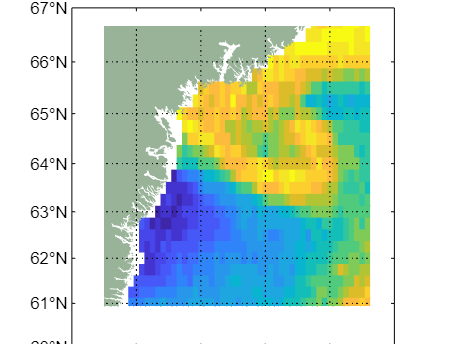


figure;
m_proj('mercator','lon',lonlim,'lat',latlim)
hold on
m_pcolor(lonbw,latbw,vaporbw);
shading flat
m_gshhs_i('patch',[.6 .7 .6],'linestyle','none');
m_grid;

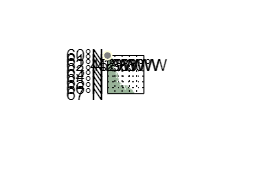

%rescale and mask "nan" as "0"
vaporbw=vapor(a:c,d:b,j);
vaporbw=rescale(vaporbw);vaporbw(isnan(vaporbw))=0;
imshow(vaporbw)

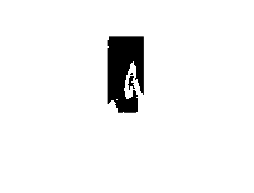

% binarize with 0.7
vaporbw(vaporbw<0.7)=0;vaporbw(vaporbw>=0.7)=1;
imshow(vaporbw)

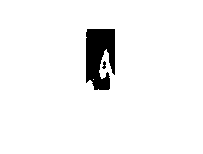

% dilate and erode
im=vaporbw;
se=strel('disk',1);%%
ied=imerode(imdilate(im,se),se); 

figure;imshow(ied)

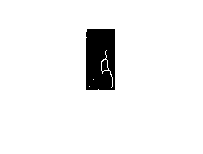

%Extraction of skeleton by ZSthin 
cons=zsthin(ied);
imshow(cons);

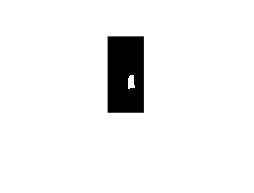

consfill=imfill(cons,'holes');
imshow(consfill)
fillarea=consfill-cons;
imshow(fillarea);

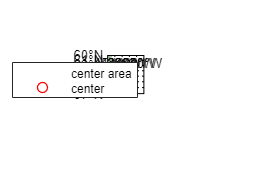

% result
fillarea(fillarea==0)=nan;
bw=fillarea;bw(isnan(bw))=0;s = regionprops(bw,'centroid');
center=cat(1,s.Centroid);ctrlon=lonbw(round(center(:,2)),round(center(:,1)));
ctrlat=latbw(round(center(:,2)),round(center(:,1)));
figure;
m_proj('mercator','lon',lonlim,'lat',latlim)
hold on
m_pcolor(lon,lat,vapor(:,:,j));
% m_plot(lonbw(zsthin(iobrcbr)>0),latbw(zsthin(iobrcbr)>0),'ro')
shading flat;
im=m_pcolor(lonbw,latbw,fillarea);im.FaceAlpha=0.5;
ctr=m_plot(ctrlon,ctrlat,'ro','linewidth',.75);
m_gshhs_i('patch',[.6 .7 .6],'linestyle','none');
m_grid;
leg=legend([im,ctr],{'center area','center'});